clear all
rng(3)

nspec = 10;
nm = 10;
np = 10;
p_length = 100;

polys = zeros(np, nm);
for i = 1:np
    polys(i, :) = create_poly(p_length, nm);
end

cons_traits_mono = rand(nspec, nm);
cons_traits_mono = cons_traits_mono ./ sum(cons_traits_mono, 2);

C = zeros(nspec, np);
for i = 1:nspec
    C(i, :) = sum((polys' .* cons_traits_mono(i, :)')', 2);
end

C = (C * nm) / 50

C =     2.1423    1.9790    2.0274    2.1096    2.0452    1.8346    2.0255    1.8123    2.0425    1.9242
    2.1295    1.8279    2.0431    2.0430    1.9278    2.0967    2.0248    2.1822    2.0221    2.1752
    1.9167    1.9937    1.8861    1.9980    2.0744    1.8611    2.0096    1.8689    2.0798    1.9806
    1.9399    2.0983    1.9248    1.9742    2.0544    1.8786    1.8877    1.7971    2.0741    2.0300
    2.0206    2.0396    2.0063    1.9624    2.1517    1.9035    2.0205    1.8823    1.8439    1.8560
    2.0101    2.1660    2.0010    1.9577    1.8649    2.0145    2.0654    1.8217    2.0665    2.0675
    2.0750    2.0729    1.9697    1.9455    1.8844    2.1086    1.9751    2.1550    2.1722    2.2670
    2.0795    2.1385    2.1753    1.9905    1.9348    2.1121    2.0259    1.9288    1.9129    1.9022
    2.1070    1.9409    1.9181    1.9210    1.8491    2.0572    2.1272    2.0291    2.0432    2.3490
    2.0712    1.8968    1.8770    1.9785    2.0831    1.8603    2.1708    1.9761    1.8


params.nspec = nspec;
params.np = np;
params.alpha = 0 * ones(nspec, 1);
params.r = 500 * ones(np, 1);
params.K = ones(np, 1);
params.m = 0.2 * ones(nspec, 1);
params.C = C;

init_abuns = ones(1, params.nspec) * 5;
init_res = ones(1, params.np) * 5;
init_state = [init_abuns, init_res];

tspan = [0 30000];
[t, sim] = ode45(@(t, y) macarthur_eqns(t, y, params), tspan, init_state);

eql = sim(end, :);
eql_abuns = eql(1:nspec);
num_coexist = sum(eql_abuns > 0.1)

num_coexist = 5

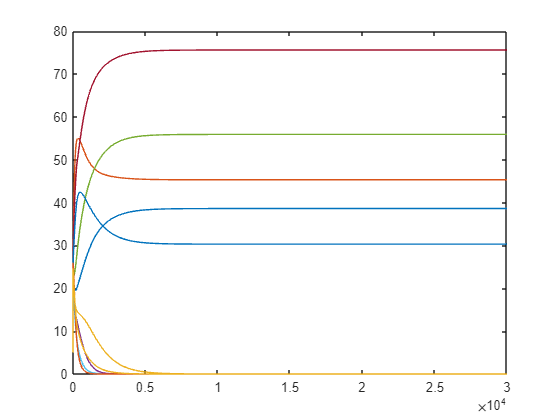


plot(t, sim(:,1:nspec))


row_tots = sum(C,2)

row_tots =    19.9427
   20.4722
   19.6689
   19.6590
   19.6867
   20.0353
   20.6254
   20.2005
   20.3417
   19.7246


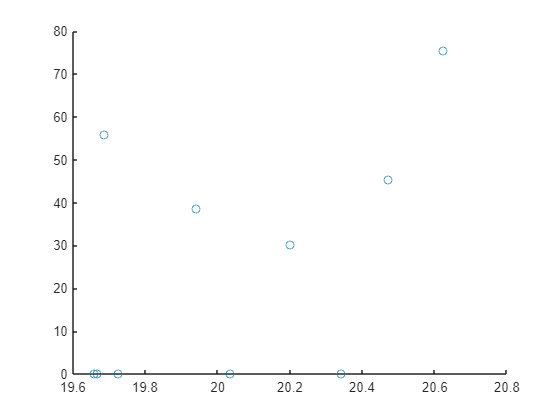


scatter(row_tots, eql_abuns)

corr(row_tots(:), eql_abuns(:))

ans = 0.5033

function counts = create_poly(p_length, nm)
    vec = randi(nm, 1, p_length);
    counts = histcounts(vec, 1:(nm+1));
end

function dydt = macarthur_eqns(~, state, params)
    N = state(1:params.nspec);
    R = state((params.nspec + 1):end);

    dNdt = params.alpha + N .* ((params.C * R) - params.m);
    dRdt = R .* (params.r .* (1 - R ./ params.K) - (params.C' * N));
    
    dydt = [dNdt; dRdt];
end